brazil = brazil_data

brazil = 168×15 table
    Country    ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15
    _______    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    _____    _____    _____

    Brazil           BRA            76      1856    0.22719    0.22719    NaN    NaN     NaN        NaN       NaN     0.028651      NaN      NaN      NaN 
  

brazil

brazil = 168×15 table
    Country    ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15
    _______    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    _____    _____    _____

    Brazil           BRA            76      1856    0.22719    0.22719    NaN    NaN     NaN        NaN       NaN     0.028651      NaN      NaN      NaN 
  

%create a population column that is total divided by PerCapita
brazil.Population = brazil.Total ./ brazil.PerCapita;
brazil

brazil = 168×16 table
    Country    ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    Population
    _______    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    _____    _____    _____    __________

    Brazil           BRA            76      1856    0.22719    0.22719    NaN    NaN     NaN   

population = population_data(population_data.CountryName == "Brazil", :)

population = 74×5 table
    CountryName    ISO3    UNcode    Year    Population
    ___________    ____    ______    ____    __________

      Brazil       BRA       76      1950    5.3955e+07
      Brazil       BRA       76      1951    5.5591e+07
      Brazil       BRA       76      1952    5.7283e+07
      Brazil       BRA       76      1953    5.9026e+07
      Brazil       BRA       76      1954    6.0828e+07
      Brazil       BRA       76      1955    6.2701e+07
      Brazil       BRA       76      1956    6.4645e+07
      Brazil       BRA       76      1957    6.6661e+07
      Brazil       BRA       76      1958    6.8736e+07
      Brazil       BRA       76      1959    7.0881e+07
      Brazil       BRA       76      1960    7.3093e+07
      Brazil       BRA       76      1961     7.533e+07
      Brazil       BR

%make the values in the population column with commas and not scientific
%notation
brazil.Population = num2str(brazil.Population, '%.0f'); % Convert Population to string format with no decimals
brazil

brazil = 168×16 table
    Country    ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    Population
    _______    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    _____    _____    _____    __________

    Brazil           BRA            76      1856    0.22719    0.22719    NaN    NaN     NaN   

%be sure to ask about what to do with inconsisten data, use population data
%for 1950-on, or extrapolate all the same way for consistency?

%now make training and test data
training = brazil(brazil.Year <= 2018, :)

training = 163×16 table
    Country    ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    Population
    _______    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    _____    _____    _____    __________

    Brazil           BRA            76      1856    0.22719    0.22719    NaN    NaN     NaN 

testing = brazil(brazil.Year > 2018, :)

testing = 5×16 table
    Country    ISO3166_1Alpha_3    UNM49    Year    Total      Coal      Oil       Gas      Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    Population
    _______    ________________    _____    ____    ______    ______    ______    ______    ______    _______    _____    _________    _____    _____    _____    __________

    Brazil           BRA            76      2019       467    61.888    299.44    67.121

testing

testing = 5×16 table
    Country    ISO3166_1Alpha_3    UNM49    Year    Total      Coal      Oil       Gas      Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    Population
    _______    ________________    _____    ____    ______    ______    ______    ______    ______    _______    _____    _________    _____    _____    _____    __________

    Brazil           BRA            76      2019       467    61.888    299.44    67.121

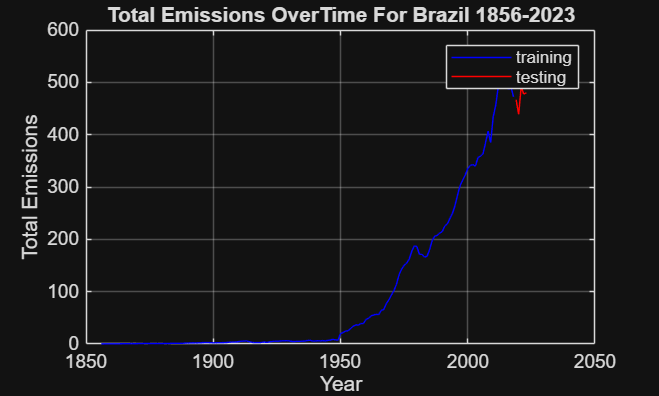

figure;
plot(training.Year, training.Total, "b", "DisplayName", "training")
xlabel("Year")
ylabel("Total Emissions")
title("Total Emissions OverTime For Brazil 1856-2023")
grid on
hold on
plot(testing.Year, testing.Total, "r", "DisplayName", "testing")
legend
hold off

%now compute group statistics to test for stationarity 

% Compute group summary
statsTotal = groupsummary(training,"Year",10,["mean","std"],"Total");
statsTotal.GroupCount = []

statsTotal = 10×3 table
     disc_Year      mean_Total    std_Total
    ____________    __________    _________

    [1850, 1867)     0.40702       0.12686 
    [1867, 1884)     0.87236       0.15725 
    [1884, 1901)       1.971       0.54619 
    [1901, 1918)      3.6675        1.1787 
    [1918, 1935)      4.7977        1.1377 
    [1935, 1952)      8.2622        4.7738 
    [1952, 1969)      46.468        15.107 
    [1969, 1986)      149.64        33.076 
    [1986, 2003)      264.17          52.8 
    [2003, 2020]      439.23        69.437 


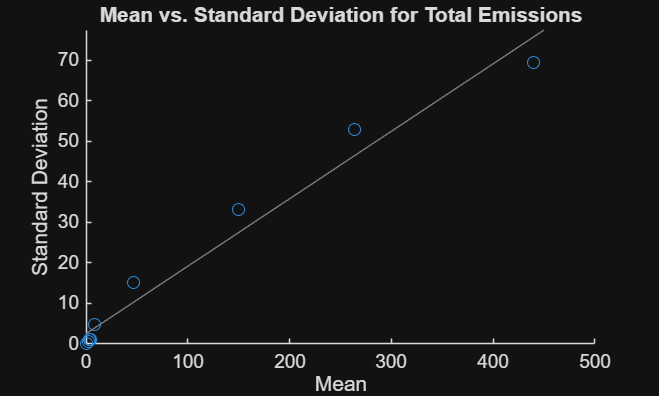

%now graph mean vs. standard deviation from above
figure;
scatter(statsTotal.mean_Total, statsTotal.std_Total)
xlabel("Mean")
ylabel("Standard Deviation")
title("Mean vs. Standard Deviation for Total Emissions")
lsline

%now make stationary
training.logTotal = log(training.Total)

training = 163×17 table
    Country    ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    Population    logTotal
    _______    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    _____    _____    _____    __________    ________

    Brazil           BRA           

%now compute group statistics for the log emissions

% Compute group summary
statsLogTotal = groupsummary(training,"Year",10,["mean","std"],"logTotal");
statsLogTotal.GroupCount = []

statsLogTotal = 10×3 table
     disc_Year      mean_logTotal    std_logTotal
    ____________    _____________    ____________

    [1850, 1867)      -0.94376         0.31718   
    [1867, 1884)      -0.15323           0.193   
    [1884, 1901)       0.63901         0.29657   
    [1901, 1918)         1.254          0.3064   
    [1918, 1935)        1.5369         0.26937   
    [1935, 1952)        2.0133         0.40608   
    [1952, 1969)         3.787         0.33667   
    [1969, 1986)         4.981         0.25088   
    [1986, 2003)         5.558         0.19851   
    [2003, 2020]        6.0732         0.15981   


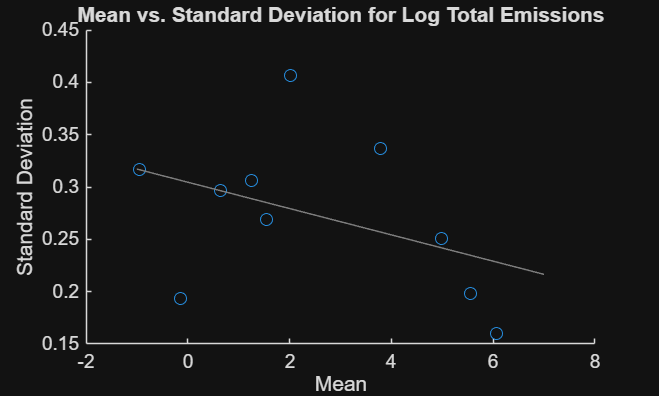

figure;
scatter(statsLogTotal.mean_logTotal, statsLogTotal.std_logTotal)
xlabel("Mean")
ylabel("Standard Deviation")
title("Mean vs. Standard Deviation for Log Total Emissions")
lsline

%now extract piecewisse linear component for logTotal emissions

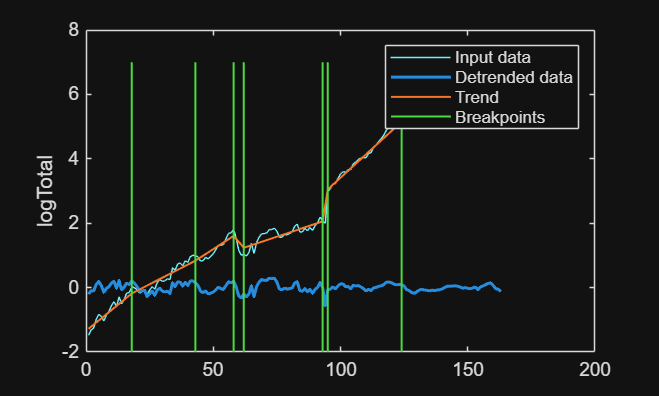

% Remove trend from input data
breakpoints = [18 43 58 62 93 95 124];
newTable4 = detrend(training(:,"logTotal"),1,breakpoints);

% Extract trend from input data
linTrend = training(:,"logTotal");
linTrend.(1) = linTrend.(1) - newTable4.(1);

% Display results
figure
plot(training.logTotal,SeriesIndex=6,DisplayName="Input data")
hold on
plot(newTable4.logTotal,SeriesIndex=1,LineWidth=1.5,DisplayName="Detrended data")
plot(linTrend.logTotal,SeriesIndex=2,LineWidth=1,DisplayName="Trend")
xbreakpoints = repelem(breakpoints,3);
ybreakpoints = repmat([ylim(gca) missing]',numel(breakpoints),1);
plot(xbreakpoints,ybreakpoints,SeriesIndex=5,LineWidth=1, ...
    DisplayName="Breakpoints")
hold off
legend
ylabel("logTotal")

clear breakpoints newTable4 xbreakpoints ybreakpoints

%extract the piecewise linaer equation from the above linear trend
%decomposition
% === Inputs ===
x = (1:height(training))';               % or replace with your actual x variable
y = training.logTotal;                   % response variable
breakpoints = [18 43 58 62 93 95 124];  % same as in your detrend code

% === Step 1: Recreate the trend that was removed ===
newTable4 = detrend(training(:,"logTotal"),1,breakpoints);
linTrend = training(:,"logTotal");
linTrend.(1) = linTrend.(1) - newTable4.(1);
y_trend = linTrend.logTotal;

% === Step 2: Fit each linear segment ===
edges = [1; breakpoints(:); numel(x)];
nSeg = numel(edges) - 1;
slopes = zeros(nSeg,1);
intercepts = zeros(nSeg,1);

for i = 1:nSeg
    idx = edges(i):edges(i+1);
    p = polyfit(x(idx), y_trend(idx), 1);  % fit y = a*x + b
    slopes(i) = p(1);
    intercepts(i) = p(2);
end

% === Step 3: Print each segment equation ===
fprintf('Piecewise-linear trend model:\n');

Piecewise-linear trend model:


for i = 1:nSeg
    if i == 1
        fprintf('x ≤ %d: y = %.6f*x + %.6f\n', breakpoints(i), slopes(i), intercepts(i));
    elseif i == nSeg
        fprintf('x > %d: y = %.6f*x + %.6f\n', breakpoints(i-1), slopes(i), intercepts(i));
    else
        fprintf('%d < x ≤ %d: y = %.6f*x + %.6f\n', breakpoints(i-1), breakpoints(i), slopes(i), intercepts(i));
    end
end

x ≤ 18: y = 0.064591*x + -1.343615


18 < x ≤ 43: y = 0.040661*x + -0.912886
43 < x ≤ 58: y = 0.051379*x + -1.373756
58 < x ≤ 62: y = -0.092118*x + 6.949090
62 < x ≤ 93: y = 0.026400*x + -0.399027
93 < x ≤ 95: y = 0.496556*x + -44.123592
95 < x ≤ 124: y = 0.072497*x + -3.837980


x > 124: y = 0.028920*x + 1.565653



% === Step 4: Build the custom equation string for Curve Fitter ===
eqnParts = strings(nSeg,1);
for i = 1:nSeg
    if i == 1
        cond = sprintf('(x <= %d)', breakpoints(i));
    elseif i == nSeg
        cond = sprintf('(x > %d)', breakpoints(i-1));
    else
        cond = sprintf('(x > %d & x <= %d)', breakpoints(i-1), breakpoints(i));
    end
    eqnParts(i) = sprintf('(%.8f*x + %.8f).*(%s)', slopes(i), intercepts(i), cond);
end
customEqn = strjoin(eqnParts, ' + ');
fprintf('\nPaste this into the Curve Fitter App:\n\n%s\n\n', customEqn);


Paste this into the Curve Fitter App:

(0.06459067*x + -1.34361528).*((x <= 18)) + (0.04066125*x + -0.91288573).*((x > 18 & x <= 43)) + (0.05137915*x + -1.37375560).*((x > 43 & x <= 58)) + (-0.09211819*x + 6.94909031).*((x > 58 & x <= 62)) + (0.02639983*x + -0.39902725).*((x > 62 & x <= 93)) + (0.49655645*x + -44.12359224).*((x > 93 & x <= 95)) + (0.07249737*x + -3.83798014).*((x > 95 & x <= 124)) + (0.02891969*x + 1.56565259).*((x > 124))



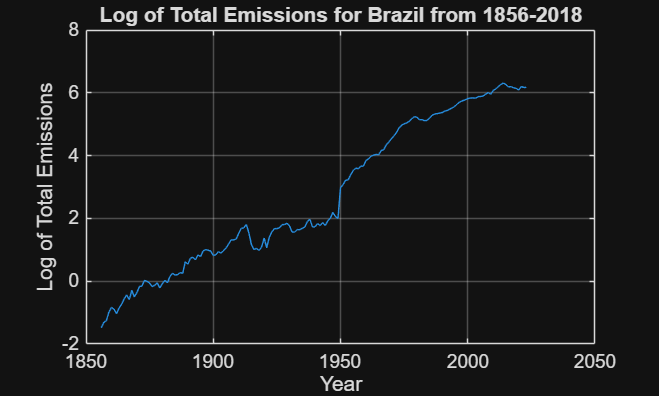

figure;
plot(training.Year, training.logTotal)
xlabel("Year")
ylabel("Log of Total Emissions")
title("Log of Total Emissions for Brazil from 1856-2018")
grid on

%create column that is logtotal minus the linear trend
training.linDetrended = training.logTotal - linTrend.logTotal

training = 163×18 table
    Country    ISO3166_1Alpha_3    UNM49    Year     Total      Coal      Oil    Gas    Cement    Flaring    Other    PerCapita    Var13    Var14    Var15    Population    logTotal    linDetrended
    _______    ________________    _____    ____    _______    _______    ___    ___    ______    _______    _____    _________    _____    _____    _____    __________    ________    

%now extract the long-term, seasonal, and remainder components using the
%find and remove trends live task

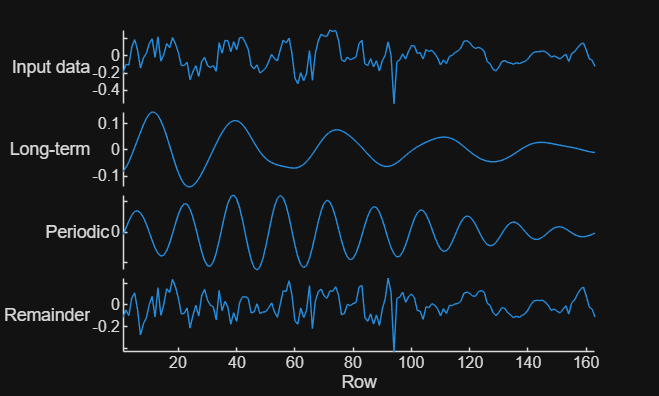

% Decompose data into long-term trend, seasonal trends, and remainder
trends = trenddecomp(training(:,"linDetrended"),"ssa",81,NumSeasonal=1);

% Display results
figure
stackedplot([training(:,18) trends],"DisplayLabels",["Input data","Long-term", ...
    "Periodic","Remainder"]);

%now create a table of all of these components
allComponents = table


allComponents =

  0×0 empty table



allComponents.Year = training.Year

allComponents = 163×1 table
    Year
    ____

    1856
    1857
    1858
    1859
    1860
    1861
    1862
    1863
    1864
    1865
    1866
    1867
    1868
    1869
    1870
    1871


allComponents.LinComp = linTrend.logTotal

allComponents = 163×2 table
    Year    LinComp 
    ____    ________

    1856      -1.279
    1857     -1.2144
    1858     -1.1498
    1859     -1.0853
    1860     -1.0207
    1861    -0.95607
    1862    -0.89148
    1863    -0.82689
    1864     -0.7623
    1865    -0.69771
    1866    -0.63312
    1867    -0.56853
    1868    -0.50394
    1869    -0.43935
    1870    -0.37476
    1871    -0.31016


allComponents.LongTermComp = trends.linDetrended_LongTerm

allComponents = 163×3 table
    Year    LinComp     LongTermComp
    ____    ________    ____________

    1856      -1.279     -0.082317  
    1857     -1.2144     -0.066419  
    1858     -1.1498     -0.045687  
    1859     -1.0853     -0.019092  
    1860     -1.0207     0.0096957  
    1861    -0.95607        0.0382  
    1862    -0.89148      0.066948  
    1863    -0.82689      0.095306  
    1864     -0.7623       0.11942  
    1865    -0.69771       0.13638  
    1866    -0.63312         0.144  
    1867    -0.56853        0.1418  
    1868    -0.50394       0.13095  
    1869    -0.43935       0.11085  
    1870    -0.37476      0.083993  
    1871    -0.31016      0.051845  


allComponents.SeasComp = trends.linDetrended_Seasonal

allComponents = 163×4 table
    Year    LinComp     LongTermComp     SeasComp 
    ____    ________    ____________    __________

    1856      -1.279     -0.082317      -0.0090059
    1857     -1.2144     -0.066419        0.013622
    1858     -1.1498     -0.045687        0.036535
    1859     -1.0853     -0.019092        0.056045
    1860     -1.0207     0.0096957        0.068051
    1861    -0.95607        0.0382        0.070607
    1862    -0.89148      0.066948        0.063686
    1863    -0.82689      0.095306         0.04875
    1864     -0.7623       0.11942         0.02684
    1865    -0.69771       0.13638      0.00065465
    1866    -0.63312         0.144       -0.026645
    1867    -0.56853        0.1418        -0.05141
    1868    -0.50394       0.13095       -0.069277
    1869    -0.43935       0.11085        -0.07801
    1870    -0.3747

%now create a table for the remainder
remainingTS = table


remainingTS =

  0×0 empty table



remainingTS.Time = training.Year

remainingTS = 163×1 table
    Time
    ____

    1856
    1857
    1858
    1859
    1860
    1861
    1862
    1863
    1864
    1865
    1866
    1867
    1868
    1869
    1870
    1871



%add remainder value, ensure it is rounded for consistency
remainingTS.Remainder = round(trends.linDetrended_Remainder,4)

remainingTS = 163×2 table
    Time    Remainder
    ____    _________

    1856     -0.1116 
    1857     -0.0456 
    1858     -0.0979 
    1859      0.0614 
    1860      0.1103 
    1861     -0.0442 
    1862     -0.2739 
    1863     -0.1706 
    1864     -0.1188 
    1865      0.0019 
    1866      0.0788 
    1867     -0.1112 
    1868      0.1579 
    1869     -0.0959 
    1870      0.0064 
    1871      0.1497 


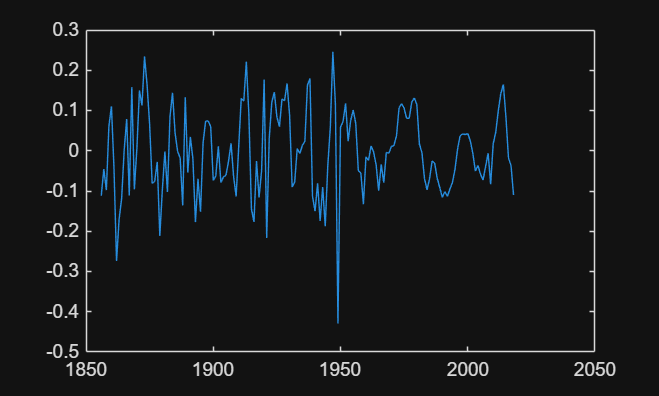

figure;
plot(remainingTS.Time, remainingTS.Remainder)

%now, we curve fit the linear, long-term, and seasonal components and
%extract the results as functions
LinMdl2 = createLinFit2(allComponents.LinComp)

LinMdl2 =      General model:
     LinMdl2(x) = (a1*x+b1).*(x<=18)+(a2*x+b2).*(x>18&x<=43)+(a3*x+b3).*(x>43&x<=
                    58)+(a4*x+b4).*(x>58&x<=62)+(a5*x+b5).*(x>62&x<=93)
                    +(a6*x+b6).*(x>93&x<=95)+(a7*x+b7).*(x>95&x<=124)+(a8*x+
                    b8).*(x>124)
     Coefficients (with 95% confidence bounds):
       a1 =     0.06459  (0.06459, 0.06459)
       a2 =     0.04066  (0.04066, 0.04066)
       a3 =     0.05138  (0.05138, 0.05138)
       a4 =    -0.09212  (-0.09212, -0.09212)
       a5 =      0.0264  (0.0264, 0.0264)
       a6 =      0.4966  (0.4966, 0.4966)
       a7 =      0.0725  (0.0725, 0.0725)
       a8 =     0.02892  (0.02892, 0.02892)
       b1 =      -1.344  (-1.344, -1.344)
       b2 =     -0.9129  (-0.9129, -0.9129)
       b3 =      -1.374  (-1.374, -1.374)
       b4 =       6.949  (6.949, 6.949)
       b5 =      -0.399  (-0.399, -0.399)
       b6 =      -44.12  (-44.12, -44.12)
       b7 =      -3.838  (-3.838, -3.838)
       b8 =     

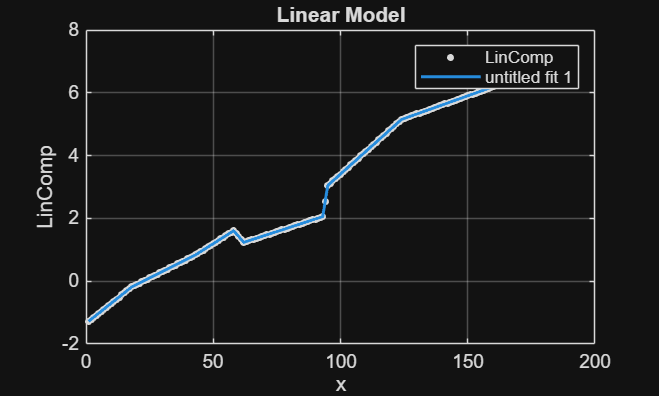

title("Linear Model")

LTMdl2 = createLTFit2(allComponents.LongTermComp)

LTMdl2 =      General model Sin8:
     LTMdl2(x) =  
                    a1*sin(b1*x+c1) + a2*sin(b2*x+c2) + a3*sin(b3*x+c3) + 
                    a4*sin(b4*x+c4) + a5*sin(b5*x+c5) + a6*sin(b6*x+c6) + 
                    a7*sin(b7*x+c7) + a8*sin(b8*x+c8)
     Coefficients (with 95% confidence bounds):
       a1 =     0.04959  (-0.5963, 0.6955)
       b1 =      0.2148  (0.08507, 0.3446)
       c1 =      -1.676  (-16.52, 13.17)
       a2 =     0.03805  (-0.3526, 0.4287)
       b2 =      0.2394  (-0.1741, 0.6528)
       c2 =      -1.047  (-41.39, 39.29)
       a3 =     0.05415  (0.02626, 0.08203)
       b3 =       0.174  (0.1573, 0.1907)
       c3 =      0.7932  (-0.8988, 2.485)
       a4 =     0.03708  (-1.292, 1.366)
       b4 =      0.2839  (-0.2915, 0.8593)
       c4 =      -2.432  (-64.68, 59.82)
       a5 =     0.04312  (-2.485, 2.571)
       b5 =      0.3033  (-0.4471, 1.054)
       c5 =      -1.346  (-70.49, 67.8)
       a6 =     0.01776  (-3.04, 3.076)
       b6 =      0.3129  

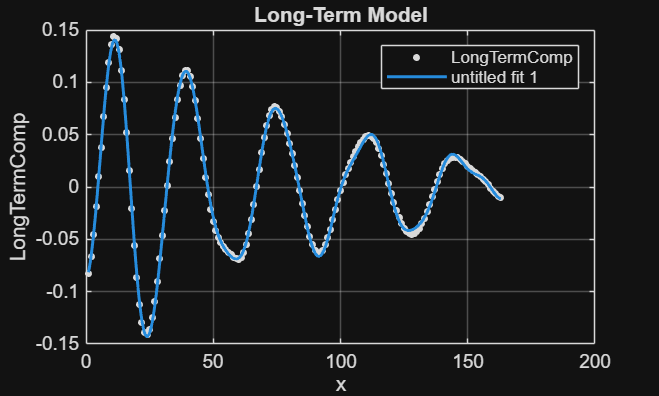

title("Long-Term Model")

SeasMdl = createSeasFit(allComponents.SeasComp)

SeasMdl =      General model Sin8:
     SeasMdl(x) =  
                    a1*sin(b1*x+c1) + a2*sin(b2*x+c2) + a3*sin(b3*x+c3) + 
                    a4*sin(b4*x+c4) + a5*sin(b5*x+c5) + a6*sin(b6*x+c6) + 
                    a7*sin(b7*x+c7) + a8*sin(b8*x+c8)
     Coefficients (with 95% confidence bounds):
       a1 =     0.06907  (0.06799, 0.07015)
       b1 =      0.3824  (0.3807, 0.384)
       c1 =     -0.4118  (-0.5328, -0.2909)
       a2 =     0.02166  (0.02025, 0.02307)
       b2 =      0.3544  (0.3529, 0.3558)
       c2 =      0.4482  (0.2894, 0.6071)
       a3 =     0.03135  (0.02827, 0.03443)
       b3 =      0.4158  (0.4143, 0.4172)
       c3 =       3.683  (3.576, 3.79)
       a4 =    0.004331  (0.003915, 0.004747)
       b4 =      0.3021  (0.2984, 0.3059)
       c4 =        2.71  (2.394, 3.026)
       a5 =     0.00367  (0.003317, 0.004023)
       b5 =      0.4676  (0.4615, 0.4738)
       c5 =       1.884  (1.383, 2.385)
       a6 =   0.0009181  (0.0006702, 0.001166)
       b

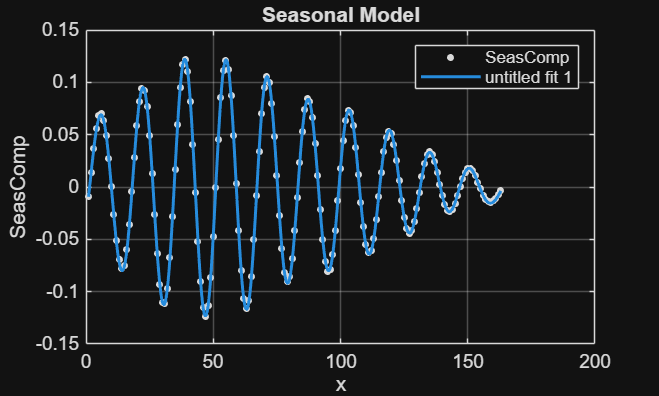

title("Seasonal Model")

remainder = table;
remainder.Remainder = remainingTS.Remainder

remainder = 163×1 table
    Remainder
    _________

     -0.1116 
     -0.0456 
     -0.0979 
      0.0614 
      0.1103 
     -0.0442 
     -0.2739 
     -0.1706 
     -0.1188 
      0.0019 
      0.0788 
     -0.1112 
      0.1579 
     -0.0959 
      0.0064 
      0.1497 


writetable(testing, "new_testing_data.csv")
writetable(training, "new_training_data.csv")
writetable(allComponents, "new_allComponents.csv")

randp = table;
randp.Remainder = remainder.Remainder

randp = 163×1 table
    Remainder
    _________

     -0.1116 
     -0.0456 
     -0.0979 
      0.0614 
      0.1103 
     -0.0442 
     -0.2739 
     -0.1706 
     -0.1188 
      0.0019 
      0.0788 
     -0.1112 
      0.1579 
     -0.0959 
      0.0064 
      0.1497 


randp.Population = training.Population

randp = 163×2 table
    Remainder    Population
    _________    __________

     -0.1116       7929671 
     -0.0456       8051713 
     -0.0979       8175698 
      0.0614       8301350 
      0.1103       8429073 
     -0.0442       8558774 
     -0.2739       8690464 
     -0.1706       8824267 
     -0.1188       8959833 
      0.0019       9097803 
      0.0788       9237728 
     -0.1112       9379914 
      0.1579       9524124 
     -0.0959       9677452 
      0.0064       9839990 
      0.1497      10012043 


randp

randp = 163×2 table
    Remainder    Population
    _________    __________

     -0.1116       7929671 
     -0.0456       8051713 
     -0.0979       8175698 
      0.0614       8301350 
      0.1103       8429073 
     -0.0442       8558774 
     -0.2739       8690464 
     -0.1706       8824267 
     -0.1188       8959833 
      0.0019       9097803 
      0.0788       9237728 
     -0.1112       9379914 
      0.1579       9524124 
     -0.0959       9677452 
      0.0064       9839990 
      0.1497      10012043 


writetable(remainder, "remainder.csv")
%create a range from 2 to 12 that skips 2

%now forecast the data, need to extract sarima function so you can fit it 
SARIMA = sarima(remainder)

SARIMA =   arima with properties:

     Description: "ARIMA(16,1,1) Model Seasonally Integrated with Seasonal AR(8) and MA(8) (Gaussian Distribution)"
      SeriesName: "Y"
    Distribution: Name = "Gaussian"
               P: 33
               D: 1
               Q: 9
        Constant: -0.00124688
              AR: {-0.318043 -0.38989 -0.295878 -0.419642 -0.204034 -0.287653 -0.26889 -0.157464 -0.169877 -0.0857322 -0.218397 -0.252945 0.0344991 -0.100945 -0.0349727 -0.275045} at lags [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16]
             SAR: {-0.494433} at lag [8]
              MA: {-0.181601} at lag [1]
             SMA: {-0.64785} at lag [8]
     Seasonality: 8
            Beta: [1×0]
        Variance: 0.0100591

%now predict data

frcst = table


frcst =

  0×0 empty table



frcst.Time = training.Year

frcst = 163×1 table
    Time
    ____

    1856
    1857
    1858
    1859
    1860
    1861
    1862
    1863
    1864
    1865
    1866
    1867
    1868
    1869
    1870
    1871


frcst.Idx = (1:163)'

frcst = 163×2 table
    Time    Idx
    ____    ___

    1856     1 
    1857     2 
    1858     3 
    1859     4 
    1860     5 
    1861     6 
    1862     7 
    1863     8 
    1864     9 
    1865    10 
    1866    11 
    1867    12 
    1868    13 
    1869    14 
    1870    15 
    1871    16 


frcstHorizon = height(frcst)

frcstHorizon = 163

y = LinMdl2(frcst.Idx)

y =    -1.2790
   -1.2144
   -1.1498
   -1.0853
   -1.0207
   -0.9561
   -0.8915
   -0.8269
   -0.7623
   -0.6977
   -0.6331
   -0.5685
   -0.5039
   -0.4393
   -0.3748


frcst.LinComp = y

frcst = 163×3 table
    Time    Idx    LinComp 
    ____    ___    ________

    1856     1       -1.279
    1857     2      -1.2144
    1858     3      -1.1498
    1859     4      -1.0853
    1860     5      -1.0207
    1861     6     -0.95607
    1862     7     -0.89148
    1863     8     -0.82689
    1864     9      -0.7623
    1865    10     -0.69771
    1866    11     -0.63312
    1867    12     -0.56853
    1868    13     -0.50394
    1869    14     -0.43935
    1870    15     -0.37476
    1871    16     -0.31016


z = LTMdl2(frcst.Idx)

z =    -0.0815
   -0.0659
   -0.0447
   -0.0189
    0.0100
    0.0402
    0.0697
    0.0963
    0.1180
    0.1330
    0.1401
    0.1383
    0.1276
    0.1086
    0.0824


frcst.LongTermComp = z

frcst = 163×4 table
    Time    Idx    LinComp     LongTermComp
    ____    ___    ________    ____________

    1856     1       -1.279     -0.081518  
    1857     2      -1.2144     -0.065913  
    1858     3      -1.1498     -0.044671  
    1859     4      -1.0853     -0.018864  
    1860     5      -1.0207      0.010038  
    1861     6     -0.95607       0.04023  
    1862     7     -0.89148      0.069683  
    1863     8     -0.82689      0.096282  
    1864     9      -0.7623       0.11799  
    1865    10     -0.69771       0.13304  
    1866    11     -0.63312       0.14007  
    1867    12     -0.56853       0.13831  
    1868    13     -0.50394       0.12764  
    1869    14     -0.43935       0.10861  
    1870    15     -0.37476       0.08245  
    1871    16     -0.31016      0.050917  


alpha = SeasMdl(frcst.Idx)

alpha =    -0.0093
    0.0133
    0.0353
    0.0535
    0.0654
    0.0690
    0.0631
    0.0483
    0.0260
   -0.0009
   -0.0287
   -0.0535
   -0.0715
   -0.0797
   -0.0764


frcst.SeasComp = alpha

frcst = 163×5 table
    Time    Idx    LinComp     LongTermComp     SeasComp 
    ____    ___    ________    ____________    __________

    1856     1       -1.279     -0.081518      -0.0093085
    1857     2      -1.2144     -0.065913        0.013304
    1858     3      -1.1498     -0.044671        0.035259
    1859     4      -1.0853     -0.018864        0.053541
    1860     5      -1.0207      0.010038         0.06544
    1861     6     -0.95607       0.04023        0.068952
    1862     7     -0.89148      0.069683        0.063123
    1863     8     -0.82689      0.096282        0.048263
    1864     9      -0.7623       0.11799           0.026
    1865    10     -0.69771       0.13304      -0.0008696
    1866    11     -0.63312       0.14007       -0.028702
    1867    12     -0.56853       0.13831         -0.05

[frcst.SARIMAFrcst, frcst.SARIMAResiduals] = forecast(SARIMA, frcstHorizon, remainder.Remainder)

frcst = 163×7 table
    Time    Idx    LinComp     LongTermComp     SeasComp     SARIMAFrcst    SARIMAResiduals
    ____    ___    ________    ____________    __________    ___________    _______________

    1856     1       -1.279     -0.081518      -0.0093085     -0.071015        0.010059    
    1857     2      -1.2144     -0.065913        0.013304     -0.036406        0.012577    
    1858     3      -1.1498     -0.044671        0.035259     -0.058442        0.013307    
    1859     4      -1.0853     -0.018864        0.053541     -0.052718        0.013895    
    1860     5      -1.0207      0.010038         0.06544     -0.043863        0.013943    
    1861     6     -0.95607       0.04023        0.068952     -0.033047         0.01438    
    1

frcst = 163×7 table
    Time    Idx    LinComp     LongTermComp     SeasComp     SARIMAFrcst    SARIMAResiduals
    ____    ___    ________    ____________    __________    ___________    _______________

    1856     1       -1.279     -0.081518      -0.0093085     -0.071015        0.010059    
    1857     2      -1.2144     -0.065913        0.013304     -0.036406        0.012577    
    1858     3      -1.1498     -0.044671        0.035259     -0.058442        0.013307    
    1859     4      -1.0853     -0.018864        0.053541     -0.052718        0.013895    
    1860     5      -1.0207      0.010038         0.06544     -0.043863        0.013943    
    1861     6     -0.95607       0.04023        0.068952     -0.033047         0.01438    
    1

frcst.sumSARIMA = frcst.LinComp + frcst.LongTermComp + frcst.SARIMAFrcst + frcst.SeasComp

frcst = 163×8 table
    Time    Idx    LinComp     LongTermComp     SeasComp     SARIMAFrcst    SARIMAResiduals    sumSARIMA
    ____    ___    ________    ____________    __________    ___________    _______________    _________

    1856     1       -1.279     -0.081518      -0.0093085     -0.071015        0.010059         -1.4409 
    1857     2      -1.2144     -0.065913        0.013304     -0.036406        0.012577         -1.3034 
    1858     3      -1.1498     -0.044671        0.035259     -0.058442        0.013307         -1.2177 
    1859     4      -1.0853     -0.018864        0.053541     -0.052718        0.013895         -1.1033 
    1860     5      -1.0207      0.010038         0.06544     -0.043863      

frcst.totalSARIMA = exp(frcst.sumSARIMA)

frcst = 163×9 table
    Time    Idx    LinComp     LongTermComp     SeasComp     SARIMAFrcst    SARIMAResiduals    sumSARIMA    totalSARIMA
    ____    ___    ________    ____________    __________    ___________    _______________    _________    ___________

    1856     1       -1.279     -0.081518      -0.0093085     -0.071015        0.010059         -1.4409       0.23672  
    1857     2      -1.2144     -0.065913        0.013304     -0.036406        0.012577         -1.3034       0.27159  
    1858     3      -1.1498     -0.044671        0.035259     -0.058442        0.013307         -1.2177       0.29591  
    1859     4      -1.0853     -0.018864        0.053541     -0.052718  

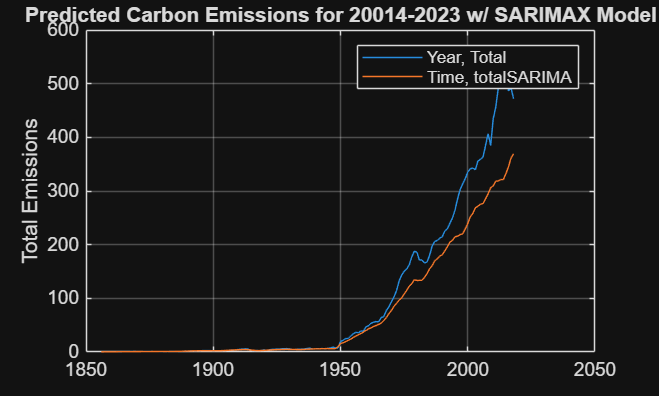

%now get error metrics
% Create Metrics Table
MetricsSARIMA = table;

% Extract actual and forecasted values
actual = training.Total; %get from test data
forecasted = frcst.totalSARIMA; %get from forecasted

% Calculate Root Mean Squared Error (RMSE) ->>> FIX
MetricsSARIMA.RMSE = rmse(forecasted, actual);

% Calculate Root Relative Squared Error (RRSE)
MetricsSARIMA.RRSE = sqrt(sum((forecasted - actual).^2) / sum((actual - mean(actual)).^2))

MetricsSARIMA = 1×2 table
     RMSE      RRSE  
    ______    _______

    48.865    0.33757


%something going horifically wrong, because individual components look
%great, but forecasted emissions are just like wayyyyy higher than they
%should be

%now try on testing data
frcsttest = table


frcsttest =

  0×0 empty table



frcsttest.Time = testing.Year

frcsttest = 5×1 table
    Time
    ____

    2019
    2020
    2021
    2022
    2023


frcsttest.Idx = (164:168)'

frcsttest = 5×2 table
    Time    Idx
    ____    ___

    2019    164
    2020    165
    2021    166
    2022    167
    2023    168


frcstHorizon = height(frcsttest)

frcstHorizon = 5

y = LinMdl2(frcsttest.Idx)

y =     6.3085
    6.3374
    6.3663
    6.3952
    6.4242


frcsttest.LinComp = y

frcsttest = 5×3 table
    Time    Idx    LinComp
    ____    ___    _______

    2019    164    6.3085 
    2020    165    6.3374 
    2021    166    6.3663 
    2022    167    6.3952 
    2023    168    6.4242 


z = LTMdl2(frcsttest.Idx)

z =    -0.0115
   -0.0104
   -0.0083
   -0.0058
   -0.0034


frcsttest.LongTermComp = z

frcsttest = 5×4 table
    Time    Idx    LinComp    LongTermComp
    ____    ___    _______    ____________

    2019    164    6.3085       -0.011454 
    2020    165    6.3374       -0.010382 
    2021    166    6.3663      -0.0083352 
    2022    167    6.3952      -0.0057976 
    2023    168    6.4242       -0.003411 


alpha = SeasMdl(frcsttest.Idx)

alpha =     0.0011
    0.0061
    0.0108
    0.0149
    0.0179


frcsttest.SeasComp = alpha

frcsttest = 5×5 table
    Time    Idx    LinComp    LongTermComp    SeasComp 
    ____    ___    _______    ____________    _________

    2019    164    6.3085       -0.011454      0.001108
    2020    165    6.3374       -0.010382     0.0060761
    2021    166    6.3663      -0.0083352      0.010795
    2022    167    6.3952      -0.0057976      0.014889
    2023    168    6.4242       -0.003411      0.017931


[frcsttest.SARIMAFrcst, frcsttest.SARIMAResiduals] = forecast(SARIMA, frcstHorizon, remainder.Remainder)

frcsttest = 5×7 table
    Time    Idx    LinComp    LongTermComp    SeasComp     SARIMAFrcst    SARIMAResiduals
    ____    ___    _______    ____________    _________    ___________    _______________

    2019    164    6.3085       -0.011454      0.001108     -0.071015        0.010059    
    2020    165    6.3374       -0.010382     0.0060761     -0.036406        0.012577    
    2021    166    6.3663      -0.0083352      0.010795     -0.058442        0.013307    
    2022    167    6.3952      -0.0057976      0.014889     -0.052718        0.013895    
    2023    168    6.4242       -0.003411      0.017931     -0.043863        0.013943    


frcsttest = 5×7 table
    Time    Idx    LinComp    LongTermComp    SeasComp     SARIMAFrcst    SARIMAResiduals
    ____    ___    _______    ____________    _________    ___________    _______________

    2019    164    6.3085       -0.011454      0.001108     -0.071015        0.010059    
    2020    165    6.3374       -0.010382     0.0060761     -0.036406        0.012577    
    2021    166    6.3663      -0.0083352      0.010795     -0.058442        0.013307    
    2022    167    6.3952      -0.0057976      0.014889     -0.052718        0.013895    
    2023    168    6.4242       -0.003411      0.017931     -0.043863        0.013943    


frcsttest.sumSARIMA = frcsttest.LinComp + frcsttest.LongTermComp + frcsttest.SARIMAFrcst + frcsttest.SeasComp

frcsttest = 5×8 table
    Time    Idx    LinComp    LongTermComp    SeasComp     SARIMAFrcst    SARIMAResiduals    sumSARIMA
    ____    ___    _______    ____________    _________    ___________    _______________    _________

    2019    164    6.3085       -0.011454      0.001108     -0.071015        0.010059         6.2271  
    2020    165    6.3374       -0.010382     0.0060761     -0.036406        0.012577         6.2967  
    2021    166    6.3663      -0.0083352      0.010795     -0.058442        0.013307         6.3103  
    2022    167    6.3952      -0.0057976      0.014889     -0.052718        0.013895         6.3516  
    2023    168    6.4242       -0.003411      0.017931     -0.043863        0.013943  

frcsttest.totalSARIMA = exp(frcsttest.sumSARIMA)

frcsttest = 5×9 table
    Time    Idx    LinComp    LongTermComp    SeasComp     SARIMAFrcst    SARIMAResiduals    sumSARIMA    totalSARIMA
    ____    ___    _______    ____________    _________    ___________    _______________    _________    ___________

    2019    164    6.3085       -0.011454      0.001108     -0.071015        0.010059         6.2271         506.3   
    2020    165    6.3374       -0.010382     0.0060761     -0.036406        0.012577         6.2967        542.77   
    2021    166    6.3663      -0.0083352      0.010795     -0.058442        0.013307         6.3103        550.23   
    2022    167    6.3952      -0.0057976      0.014889     -0.052718        0.01

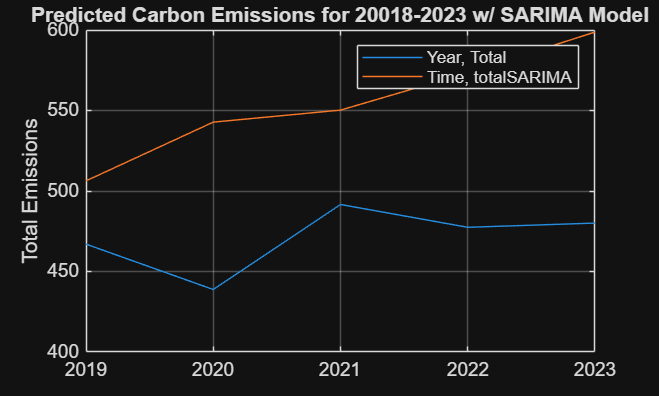

figure
plot(testing,"Year","Total")
hold on
plot(frcsttest,"Time","totalSARIMA")
grid on
title("Predicted Carbon Emissions for 20018-2023 w/ SARIMA Model")
ylabel("Total Emissions")
legend
hold off

%now get error metrics
% Create Metrics Table
MetricsSARIMA = table;

% Extract actual and forecasted values
actual = testing.Total; %get from test data
forecasted = frcsttest.totalSARIMA; %get from forecasted

% Calculate Root Mean Squared Error (RMSE) ->>> FIX
MetricsSARIMA.RMSE = rmse(forecasted, actual);

% Calculate Root Relative Squared Error (RRSE)
MetricsSARIMA.RRSE = sqrt(sum((forecasted - actual).^2) / sum((actual - mean(actual)).^2))

MetricsSARIMA = 1×2 table
     RMSE     RRSE
    ______    ____

    88.403    4.94


%something going horifically wrong, because individual components look
%great, but forecasted emissions are just like wayyyyy higher than they
%should be

%now try by adding the population